# Pipeline to track the LED from the recorded video and normalise track co-rdinates - Single video example

#### First need to get the file path for the behaviour video to be analysed:

clear all

Session_ID = 'mu46_day2_230915_s3'; %Name your session

path = '';
if isempty(path)
    %get the name of the video and the file path change file path for
    %convenience
    [video path] = uigetfile('\\rdsfcifs.acrc.bris.ac.uk\Mellor_Laboratory\Mellor Lab data\Matt Udakis\Data\Inscopix\Experiments\Exp_005_OLM_GCaMP\data\*'); %get the name of the video and the file path
end
vid_path = fullfile(path,video);

% create a video reader object from the video path
v = VideoReader(vid_path);

#### **Create a new folder 'Tracked_data' to save the tracked data files.**

dir_idcs   = strfind(path,filesep); %finds the index of folder seperators
save_dir = path; % 
%save_dir = "C:\Users\mu16645\OneDrive - University of Bristol\Bristol Uni\Data\Miniscope\Batch3 - experiment\Novelty_check\MU14\tracked_behav"
Analysed_path = fullfile(save_dir,'Tracked_data'); % new file path with new folder analysed to store analysed data.
mkdir(Analysed_path); %create the new dir for saving data

## Need to find the video frame that corresponds to start of the calcium imaging data

The video has a static LED that lights up with the calcium imaging is being recorded. 

We need to find the first frame that the LED lights up and then the frame in which the LED goes off. To do this we can use the custom function GetfirstLED() 

- GetfirstLED()  takes the video reader object, the threshold for the LED intensity and the video frame to start looking for the LED.

- the function will ask user to draw a square around where the LED in the video is located

The subsequent code will plot out the video frames before and after the LED switch to manually confirm accuracy. 

[15:17:07] please draw ROI around LED, then double click


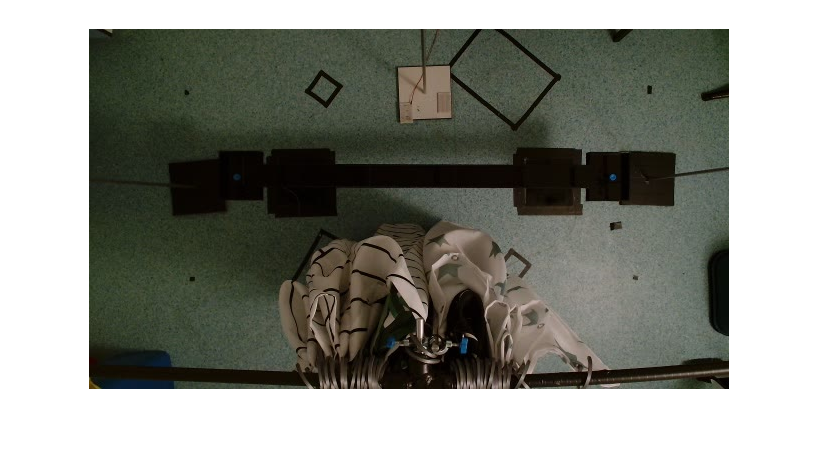

[15:17:13] LED ROI set
[15:17:16] First LED flash at frame 1360
[15:17:18] Last LED flash at frame 19306


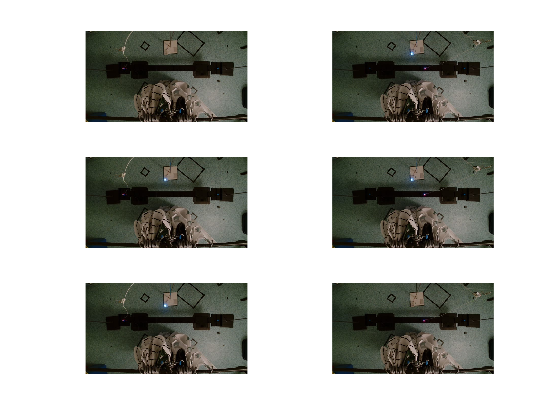

[First_LED, log, Last_LED] = GetfirstLED(v,'threshold',90,'startframe',100);

## Verify the above image: left pannel LED (off - on - on) right pannel LED (on - on - off):

Sometime Last_LED will nee changeing by a few values - use the next cell to alter the last_LED. 

check the last LED if it looks off and manully correct.

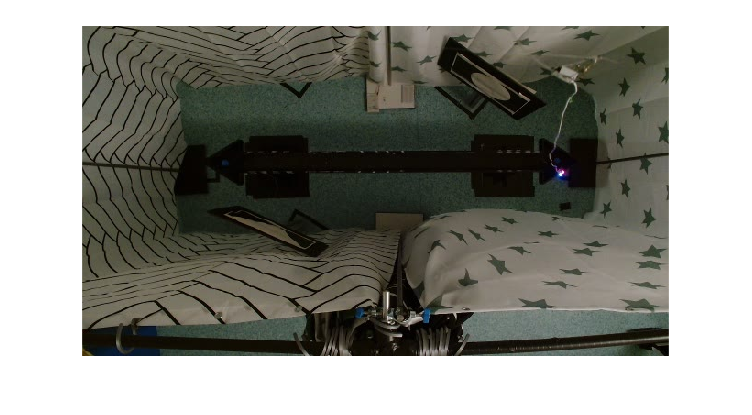

figure
frame = read(v,Last_LED+2);
imshow(frame)

%Last_LED = Last_LED+1

Last_LED = 18195

## Crop the video for tracking

In some instances it helps to crop the top and the bottom of the video:

    - sometimes the calcium imaging recording LED or the tape on the floor can be picked up in the tracking so its good to crop this out if possible

*n.b. if you dont get an output try altering the crop values*

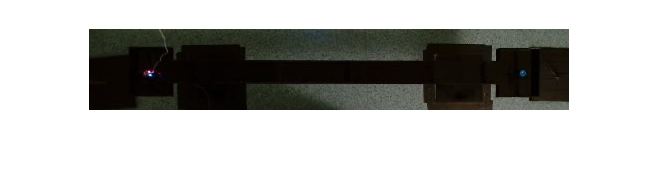

%set the top and bottom crop in pixels
y_crop = 105;
bot_y_crop = 175;
x_crop = 90;
right_x_crop = 70;
Frame_to_read = First_LED;
% show a frame of the video frame that will be used for tracking
figure
frame = read(v,Frame_to_read);
imshow(frame(y_crop:end-bot_y_crop,(1+x_crop):end-right_x_crop,:))

### Tracking the head LEDS

The head LEDs can be tracked using the function track_LEDs()

    This function uses thresholds to find the head LEDs these can be tricky to set. 

**Use the below functions threshold_select()  with the live variable slider to select the best thresholds:**

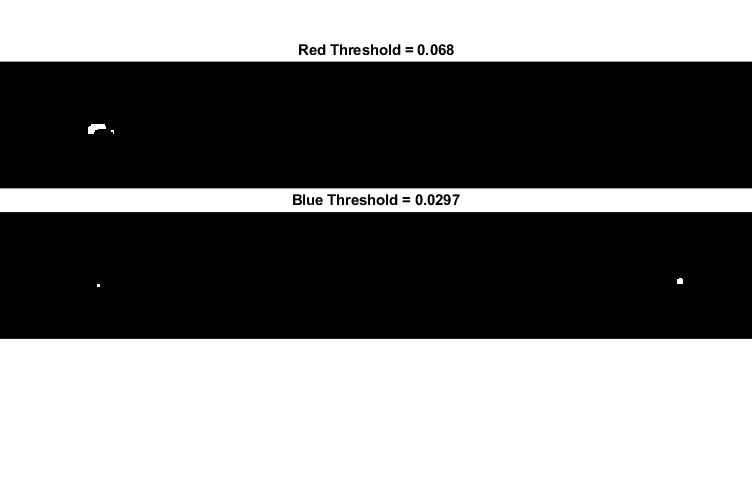

red_threshold = 0.068;
frame_r = threshold_select(v,'r', Frame_to_read, red_threshold,'foregroundDetect',false,'dilate',false);

blue_threshold = 0.0297;
frame_b = threshold_select(v,'g', Frame_to_read, blue_threshold,'foregroundDetect',false,'dilate',false);

figure('Position', [10 10 900 600]);
ax1 = subplot(2,1,1);
ax1.Position = [0 0.5 1 0.5];
imshow(frame_r(y_crop:end-bot_y_crop,x_crop:end-right_x_crop,:))
title(strcat("Red Threshold = ", string(red_threshold)));
ax2 = subplot(2,1,2);
ax2.Position = [0 0.2 1 0.5];
imshow(frame_b(y_crop:end-bot_y_crop,x_crop:end-right_x_crop,:))
title(strcat("Blue Threshold = ", string(blue_threshold)));

## Tracking the head LEDS

The head LEDs can be tracked using the function track_LEDs()

track_LEDs() takes several inputs:

- **video:** video to be tracked 

- **First and last frame:** first and last frame to be analysed. This can be sortened if you want to test parameters

- **The red and green(/blue) LED thresholds****:** these thresholds need to be determined using the threshold_select

- **crop:** wether to crop the video and if so 'ycrop' and 'botycrop'

- **interpolate****:** this fills in the missing values of the tracking if no LED is detected

#### Track the head LEDs:


try
      
[red_cords, blue_cords, Frame_time] = track_LEDs(v,'first_frame', First_LED,...
                                        'last_frame', Last_LED, ...
                                        'red_threshold', red_threshold, ...
                                        'track_blue', true, ...
                                        'blue_threshold', blue_threshold,...
                                        'green_threshold', blue_threshold,......
                                        'crop_x', true,...
                                        'xcrop',x_crop,...
                                        'rigxcrop',right_x_crop,...
                                        'crop_y', true,...
                                        'ycrop',y_crop,...
                                        'botycrop',bot_y_crop,...
                                        'interpolate', false,...
                                        'foregroundDetect',false,...
                                        'dilate',false);
                                        
catch ME
fprintf(strcat('Failed Tracking'," ",Session_ID, ': %s\n'), ME.message);

end


%calculate some metrics on the success of the tracking
number_of_r_nans = sum(isnan(red_cords(:,1)));
percent_error_r = (number_of_r_nans / size(red_cords,1))*100;

number_of_b_nans = sum(isnan(blue_cords(:,1)));
percent_error_b = (number_of_b_nans / size(blue_cords,1))*100;

disp(' ');...
disp(strcat("Red coordinates failed on ",string(percent_error_r),'% frames'));...
disp(strcat("Blue coordinates failed on ",string(percent_error_b),'% frames'));

Red coordinates failed on 0.02786% frames


Blue coordinates failed on 0% frames


## Interpolate the co-ordinates:

The tracking returns a NaN if it fails to detect the LED, the percentage failure is calculated above. 

To fill in the missing NaN values we can run a simple interpolation of the cooridinates. 

*n.b. Interpolation can be included in the track_LED function but it is prudent to first assess the error rate of the tracking first. If the error rates are high, the thresholds for the LEDs should be altered and the tracking re-run* 

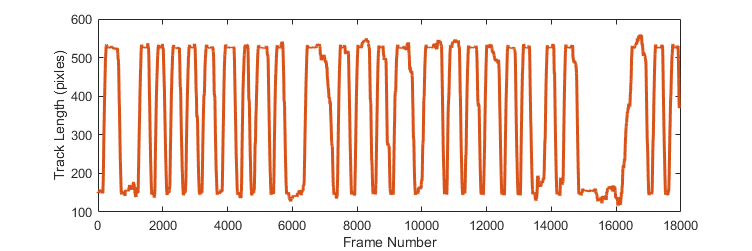

%red_cords = pre_interp_red_cords;
pre_interp_red_cords = red_cords;

red_cords = nan_interp(red_cords);
blue_cords = nan_interp(blue_cords);

figure('Position', [10 10 1200 400])
plot(red_cords(:,1))
hold on 
plot(pre_interp_red_cords(:,1),'LineWidth',2.5)
xlabel('Frame Number')
ylabel('Track Length (pixles)')

% nan_interp() simple linear interpolation based on the NaN variables   

#### Plot out the LED paths for both of the LEDs

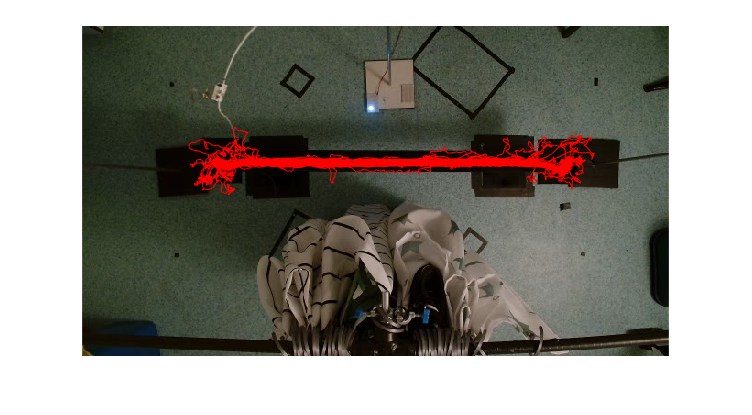

figure
imshow(read(v,First_LED))
hold on
plot(red_cords(:,1),red_cords(:,2), 'color','r');

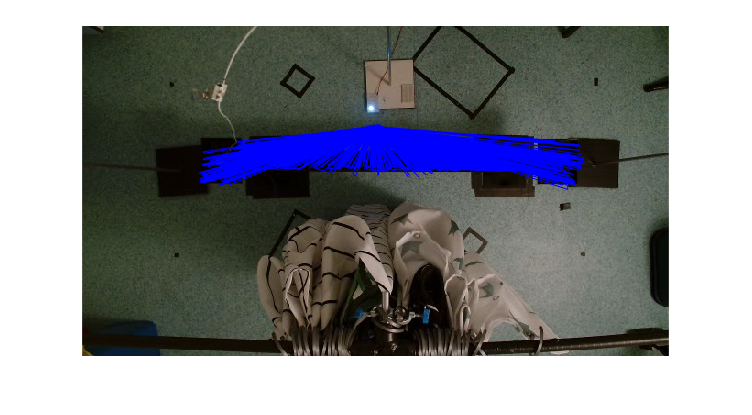

figure
imshow(read(v,First_LED))
hold on
plot(blue_cords(:,1),blue_cords(:,2), 'color','b');

## Normalise the co-ordinates

Its important to have the co-ordinates normalised to the length of the track in cm and to straighted the track just incase there is a slight tilt in the camera feed:

The function norm_coords will ask user to: 

          1. straighten the image  and then 

- There is a horizontal line that can be moved to help align the track to horizontal. 

- A box will allow the frame to be rotated, double click inside the box when frame is straightened. 

           2 . crop the image.

- Move the rectangle over the edges of the track  *n.b.use the reward zones as the coundries for the crop.*

- Double click the rectangle to complete crop

#### Define the length of the track:

define the length of the actual track in cm. *n.b. track length is entire track including the reward zone*

track_length = 141;
reward_length = 14;

#### Run the normalisation function:

[norm_red_cordinates_cm,norm_red_cordinates, norm_outputs] = norm_coords(v,red_cords,...
                                                                    'start_frame', First_LED,...
                                                                    'track_length',track_length,...
                                                                    'reward_length',reward_length);


track_rotation = norm_outputs.track_rotation;
track_crop = norm_outputs.track_crop;

[norm_blue_cordinates_cm, norm_blue_cordinates]  = norm_coords(v,blue_cords, ...
                                                                'start_frame', First_LED,...
                                                                'rotation',track_rotation,...
                                                                'crop',track_crop,...
                                                                'track_length',track_length,...
                                                                'reward_length',reward_length);
    

Oportunity to switch to the best track coordinates usually use red co-ordinates but sometimes other LED tracks better

tracked_norm_coords_cms = norm_red_cordinates_cm;
%tracked_norm_coords_cms = norm_blue_cordinates_cm;


#### Plot the outcome of the normalisation function to check that the cooridinates corectly scaled. 

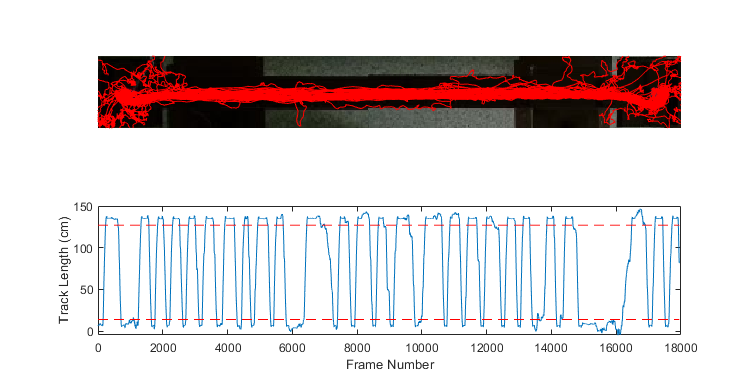

%%finish off the plotting figure 
figure('Position', [10 10 1200 600])
subplot(2,1,1)

    imshow(norm_outputs.cropped_track);
    hold on
    plot(norm_red_cordinates(:,1),norm_red_cordinates(:,2), 'color','r')
    hold on
    %plot(norm_blue_cordinates(:,1),norm_blue_cordinates(:,2),'color','b')
subplot(2,1,2)
    plot(tracked_norm_coords_cms(:,1))
    hold on 
    line([1, size(tracked_norm_coords_cms(:,1),1)],[reward_length reward_length],'Color','red','LineStyle','--')
    hold on 
    line([1, size(tracked_norm_coords_cms(:,1),1)],[(track_length-reward_length) (track_length-reward_length)],'Color','red','LineStyle','--')
    xlabel('Frame Number')
    ylabel('Track Length (cm)')

## Calculate the Frame times 

This is a rough calculation of the actual frame times based on a 10 minute recording session.

- Often with a stable webcam feed with 0 skipped frames the number of video frames is consistent for all recordings `n.b. 17959 frames seems to be the consistent number` 

- If frame rate is stable then this approach works ok. 

- If the frame rate is not stable a more accurate approach is to get the video Frame timestamps that are stored in the tracking csv file. for an approach to that see below

- The best approach is to have a sync signal from the inscopix box to and LED on the floor in the video field of view. This can then be used to most accuratly sync the inscopix to the video feed. (this was not implemented due to having stable webcame aquistion).

recording_length = 10; %length of the calcium recording in mins  

Take the number of Frames and assuming a consitant frame rate assign time equally to each Frame

behave_frames = size(First_LED:Last_LED,2);

%  starttime = 0;
%  endtime = 443.9519;
%  frame_time = linspace(starttime,endtime,behave_frames).';


frame_time = linspace(0,(recording_length*60),behave_frames).';
frame_time_min = frame_time/60;

frame_number = behave_frames;
%frame_time = s2_frametime_interpolated.';
%frame_time_min = frame_time/60;


## (Optional) Behviour frame times from tracked csv - load csv

during acquistion the frame timestamps for the recorded video were aquired this gives the most accurate times for the frames

[videotrack_file videotrack_dir] = uigetfile(strcat(path,'/*.csv'),'Select videotrack file');
%videotrack_data = importdata(fullfile(videotrack_dir,videotrack_file));
video_track_table = readtable(fullfile(videotrack_dir,videotrack_file));

*n.b. If the csv doesnt have text in the first row of the csv the function readtable gives NaN's for entire column. To fix open up the csv and add some text to the first row. *

## (Optional) Behviour frame times from tracked csv - processing

This approach looks for the video recording tag in the csv which highlights when the video frame is writted to disk.The number of these frames should exactly match the number of frames in the video file.

From the frames deemed as recording you can get the timestamp that they were aquired this gives you the most accurate time of the video timestamps. 

%videotrack_data_val = videotrack_data.textdata;
%videotrack_data_val(1,:) = [];
%convert the video track data into a large table
%videotrack_data_val = cell2table(videotrack_data_val,"VariableNames",videotrack_data.textdata(1,:));
%videotrack_data_val = video_track_table;
recording = strcmpi(video_track_table.Recording, 'true');
log = video_track_table.("EventLog");
start_recording = find(contains(log,'recording'))

start_recording = 8104

start_recording = start_recording(1)

start_recording = 8104

assert(recording(start_recording) == 1 & recording(start_recording-1) == 0),"recording time not accurate";
recording(1:start_recording-1) = 0;
assert(find(diff(recording) == 1)+1 == start_recording, "recording time not accurate");


frame_time_raw = video_track_table.Timestamp(recording);
frame_number_raw = video_track_table.Frame_number(recording);

frame_time_filt = frame_time_raw(First_LED:Last_LED);
frame_time = frame_time_filt - frame_time_filt(1);
assert(size(frame_time,1) == size(tracked_norm_coords_cms(:,1),1),"number of video frames does not match number of timestamps")

%check the frame time is 10 mins
frame_time(end)

ans = 599.9744

frame_time_min = frame_time/60;
recording_length = round(frame_time_min(end))

recording_length = 10

## Calculate the Velocity of the animal: 

Place cell calculations are always calculated when the animal is running above a certain threshold. 

We can use the coordinates and framne time data to caculate the instantaneous velocity and use this to filter the co-ordinates

Calculate the distance between each of the coordinates and then devide this by the time between frames.

%takes the distance between each x and y coordinate.
%distance = hypot(diff(norm_red_cordinates_cm(:,1)),diff(norm_red_cordinates_cm(:,2))); 

%takes the absolute distance from just the x-cordinate. (makes it a bit
%cleaner
distance = abs(diff(tracked_norm_coords_cms(:,1)));
velocity = distance./diff(frame_time(1:end,:));

we can smooth the velocity using a smooth filter to denoise the signal.

vel_smooth = 60;
velocity_smoothed = smooth(velocity,vel_smooth);
velocity_smoothed(end+1) = velocity_smoothed(end); %append another value to end for dimention consitancy

## Velocity Filter 

Its common to filter the data based on the velocity of the animal, frames where the velocity is above a certain threshold are used in the analysis

The velocity filter is often fixed at a set speed in this case 7cm/s

velocity_thresh = 7; 

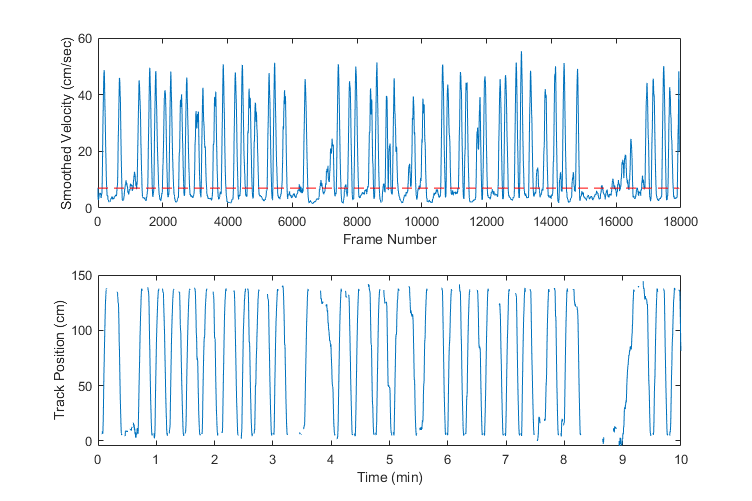

%% filter for velocity
vel_filt = [];
vel_filt = tracked_norm_coords_cms;
vel_filt(~(velocity_smoothed>velocity_thresh),:)=NaN;


figure('Position', [10 10 900 600])
    subplot(2,1,1)
        plot(velocity_smoothed);
        xlabel("Frame Number")
        ylabel("Smoothed Velocity (cm/sec)")
        line([1, size(velocity_smoothed(:,1),1)],[velocity_thresh velocity_thresh],'Color','red','LineStyle','--')
    subplot(2,1,2)
        plot(frame_time_min,vel_filt(:,1))
        xlabel('Time (min)')
        ylabel('Track Position (cm)')

## Get the Run direction dual LEDs

The dual head LED on the microscope allows to calculate the direction of movement. We can split the frames into left and right direction frames. 

In some cases the camera failed to pick up the second LED and so only use this if both LEDs were tracked.

We can then define epochs of runs which is defined as a run of a defined distance in one direction.

%% get the run direction

LED_dist = 0.01; %set the distance between the LEDs in cms used as minimum distance between the LEDs to be classed as left/right facing

frame_direction = get_direction(norm_red_cordinates_cm,norm_blue_cordinates_cm,LED_dist);


## Get the Run direction single LED

In some cases the camera failed to pick up the second LED and so direction can be calculated from previous possition location.

frame_direction = get_direction_singleLED(tracked_norm_coords_cms);

## Split into Runs

The dual head LED on the microscope allows to calculate the direction of movement. We can split the frames into left and right direction frames. 

We can then define epochs of runs which is defined as a run of a defined distance in one direction.

Next we can filter for successfull runs. Here the run must be a certain distance (run_thresh) in cm for it to be included

%set the distance threshold in cm for the minimum run distance
run_thresh = 10;


vel_filt_left = vel_filt;
vel_filt_left(frame_direction~=1,:)=NaN; % for every direction frame that is not right (i.e false aka left) make it a nan

vel_filt_right = vel_filt;
vel_filt_right(frame_direction~=0,:)=NaN;

Next using the function get_laps() we can split the data into runs.

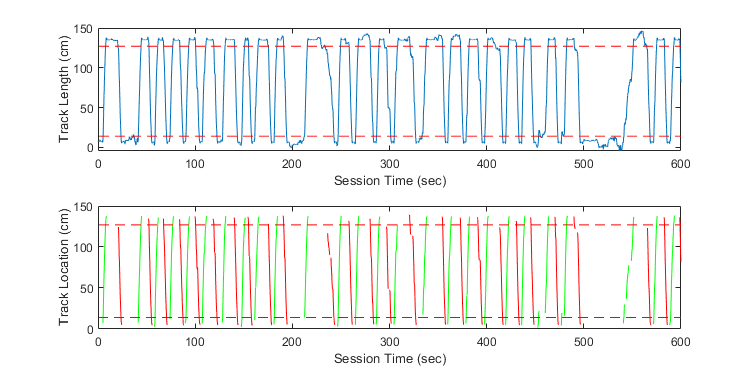

[left_runs, left_epochs, right_runs, right_epochs] = get_runs(vel_filt_left, vel_filt_right,run_thresh);


% plot out the data to confirm accuracy of the runs
figure('Position', [10 10 1200 600])
subplot(2,1,1);
    plot(frame_time,tracked_norm_coords_cms(:,1))
    hold on 
    line([1, max(frame_time)],[reward_length reward_length],'Color','red','LineStyle','--')
    line([1, max(frame_time)],[(track_length-reward_length) (track_length-reward_length)],'Color','red','LineStyle','--')
    xlabel('Session Time (sec)')
    ylabel('Track Length (cm)')
subplot(2,1,2);
    plot(frame_time,left_runs,'r')
    hold on 
    plot(frame_time,right_runs,'g')
    line([1, max(frame_time)],[reward_length reward_length],'Color','red','LineStyle','--')
    line([1, max(frame_time)],[(track_length-reward_length) (track_length-reward_length)],'Color','red','LineStyle','--')
    xlabel("Session Time (sec)")
    ylabel("Track Location (cm)")

## Save the data into a data structure


if isempty(Session_ID)
    Session_ID = video;
end
    sessiondata = struct;
    sessiondata.Session_ID = Session_ID; 
    sessiondata.Video_path = vid_path;
    
    sessiondata.frame_time = frame_time; 
    sessiondata.cropped_track = norm_outputs.cropped_track;

    sessiondata.coords.red_cords = red_cords;
    sessiondata.coords.blue_cords = blue_cords;    
    sessiondata.coords.norm_red_cordinates_cm = norm_red_cordinates_cm;
    sessiondata.coords.norm_blue_cordinates_cm = norm_blue_cordinates_cm;
    sessiondata.coords.norm_red_cordinates = norm_red_cordinates;
    sessiondata.coords.norm_blue_cordinates = norm_blue_cordinates;
    sessiondata.coords.tracked_norm_coords_cms = tracked_norm_coords_cms;
    
    sessiondata.runs.right_runs = right_runs;
    sessiondata.runs.right_epochs = right_epochs; 
    sessiondata.runs.left_runs = left_runs;
    sessiondata.runs.left_epochs = left_epochs;
    
    sessiondata.velocity = velocity_smoothed;

    sessiondata.analysis_vars.run_thresh = run_thresh;
    sessiondata.analysis_vars.LED_dist = LED_dist;
    sessiondata.analysis_vars.frame_direction = frame_direction;
    sessiondata.analysis_vars.velocity_thresh = velocity_thresh;
    sessiondata.analysis_vars.vel_smooth = vel_smooth;
    sessiondata.analysis_vars.recording_length = recording_length;  
    sessiondata.analysis_vars.track_length = track_length;
    sessiondata.analysis_vars.reward_length = reward_length;
    sessiondata.analysis_vars.red_threshold = red_threshold;
    sessiondata.analysis_vars.blue_threshold = blue_threshold;
    sessiondata.analysis_vars.crops.y_crop = y_crop;
    sessiondata.analysis_vars.crops.bot_y_crop = bot_y_crop;
    sessiondata.analysis_vars.crops.right_x_crop = right_x_crop;
    sessiondata.analysis_vars.crops.x_crop = x_crop;


    sessiondata.analysis_vars.first_last_LED = [First_LED Last_LED];
    sessiondata.analysis_vars.norm_outputs = norm_outputs;
        



save(strcat(Analysed_path,'\',Session_ID,'_tracked_data.mat'),'sessiondata');
disp(strcat("Date: ", strcat(Session_ID,'_tracked_data.mat')));...
disp(strcat("Saved at: ", Analysed_path));

Date: mu46_day2_230915_s3_tracked_data.mat


Saved at: \\rdsfcifs.acrc.bris.ac.uk\mellor_laboratory\Mellor Lab data\Matt Udakis\Data\Inscopix\Experiments\Exp_005_OLM_GCaMP\data\mu46\20230915_day2_squ-tri-squ\Session3\Tracked_data
